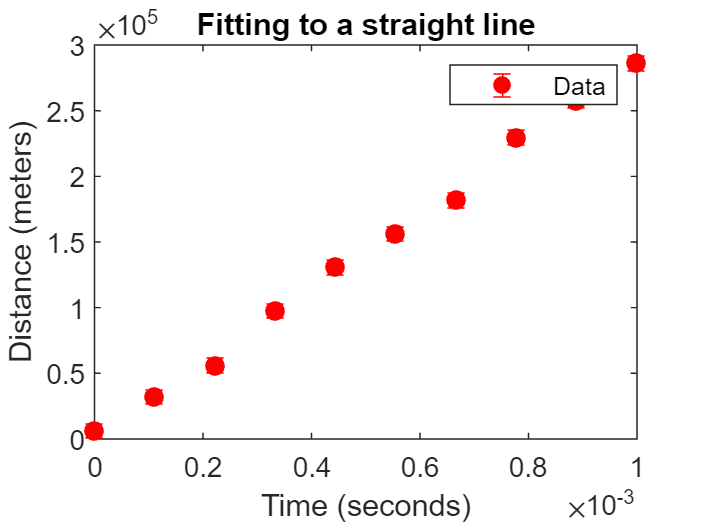

% Clear the workspace and close all open figures
clear;
clc;
close all;

% Load the data from the provided file
load('Speed_of_light_data.mat');

% Create the first figure for data visualization
figure(1)

% Plot the data points with error bars in red
errorbar(time, distance, error*ones(size(distance)), 'red.','MarkerSize',20)

% Add a legend, title, and labels to the plot
legend('Data')
title('Fitting to a straight line')
xlabel('Time (seconds)');
ylabel('Distance (meters)');

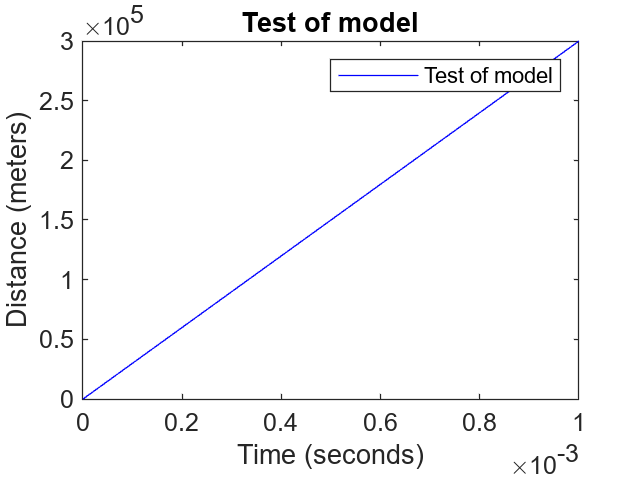


% Define the model function for fitting
modelfun = @(b, x) b(1) * x + b(2);

% Test the model with an initial guess [3e8 0]
test_distance = modelfun([3e8 0], time);

% Create the second figure for testing the model
figure(2)

% Plot the test data in blue
plot(time, test_distance, 'blue-')

% Add a legend, title, and labels to the plot
legend('Test of model')
title('Test of model')
xlabel('Time (seconds)');
ylabel('Distance (meters)');


% Create the third figure for comparing the model to data
figure(3)

hold on %allows for the program to add multiple variables to the graph

% Plot the test data in blue
plot(time, test_distance, 'blue-')

% Plot the data points with error bars in red
errorbar(time, distance, error*ones(size(distance)), 'red.','MarkerSize',20)

% Add a legend, title, and labels to the plot
legend('Test of model', 'Data')
title('Test of model')
xlabel('Time (seconds)');
ylabel('Distance (meters)');

hold off %stops the hold

% Define the initial parameter guess for the nonlinear model
start = [3e8 0];

% Fit the data to the nonlinear model
mdl = fitnlm(time, distance, modelfun, start)

mdl = Nonlinear regression model:
    y ~ b1*x + b2

Estimated Coefficients:
           Estimate         SE         tStat       pValue  
          __________    __________    _______    __________

    b1    2.8624e+08    5.6118e+06     51.006    2.4181e-11
    b2        540.54        3328.8    0.16238       0.87503


Number of observations: 10, Error degrees of freedom: 8
Root Mean Squared Error: 5.66e+03
R-Squared: 0.997,  Adjusted R-Squared 0.997
F-statistic vs. zero model: 4.52e+03, p-value = 6.12e-13

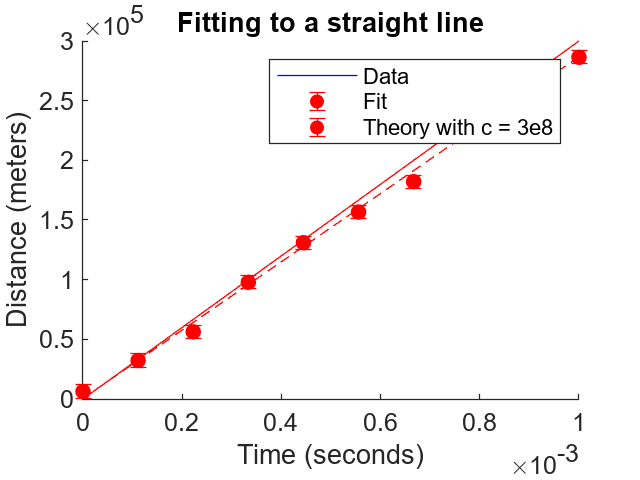


% Create the fourth figure for fitting results
figure(4)

hold on %allows for the program to add multiple variables to the graph

% Plot the data points with error bars in red
errorbar(time, distance, error.*ones(size(distance)), 'red.','MarkerSize',20)

% Plot the fitted model in red dashed line
plot(time, predict(mdl, time'), 'red--')

% Plot the theoretical model with c = 3e8 in red solid line
plot(time, 3e8 * time, 'red-')

% Add a legend, title, and labels to the plot
legend('Data', 'Fit', 'Theory with c = 3e8')
title('Fitting to a straight line')
xlabel('Time (seconds)');
ylabel('Distance (meters)');

hold off %stops the hold


% Extract the estimated value of the speed of light (c) and its standard error
estimate_c = mdl.Coefficients{1,1};
error_on_c = mdl.Coefficients{1,2};

% Calculate the number of standard deviations between the estimate and the true value
number_of_standard_deviations = (3e8 - estimate_c) / error_on_c;

% Calculate the chi-squared value
chisq = sum(((predict(mdl, time')' - distance) ./ (error*ones(size(distance)))).^2);

% Calculate the chi-squared per degree of freedom (dof)
chisq_per_dof = chisq / 8; % Assuming 8 data points in this example
